% Neural Spike Detector (Simulation + Detection + Evaluation + Plots)

clear; clc; close all;

% 1) Parameters
Fs        = 20000;        % Sampling rate (Hz)
T         = 10;           % Duration (s)
N         = Fs*T;         % Total samples
t         = (0:N-1)/Fs;   % Time vector

% Spike train parameters
meanFR    = 12;           % Mean firing rate (Hz)
refrac_ms = 1.5;          % Refractory (ms) for detection & sim safety
refrac_s  = refrac_ms/1000;

% Noise & spike waveform
whiteStd  = 18e-6;        % White noise std (V)
pinkAmp   = 8e-6;         % 1/f noise amplitude (V)
spkAmp    = -120e-6;      % Negative-going spike amplitude (V)
spkWidth  = 0.8e-3;       % Spike full width ~0.8 ms

% Detection
kThresh   = 5;            % Threshold multiplier (robust sigma)
detectPolarity = -1;      % -1 = detect negative peaks
detRefrac = refrac_s;     % Refractory for detector (s)
matchTol  = 1e-3;         % Match tolerance vs GT (±1 ms)

rng(7);                   % Reproducibility

% 2) Ground Truth Spike Train 
% Homogeneous Poisson-like ISIs, enforcing refractory, toolbox free.
spikeTimes = [];
tCurr = 0.05;                            % avoid very start
while tCurr < (T-0.05)
    % Exponential ISI via inverse-CDF: ISI = -log(1-U)/lambda
    isi = -log(1 - rand)/meanFR;        % no Statistics Toolbox needed
    tCand = tCurr + isi;
    if isempty(spikeTimes) || (tCand - spikeTimes(end)) >= refrac_s
        if tCand < (T-0.05)
            spikeTimes(end+1) = tCand; %#ok<SAGROW>
        end
    end
    tCurr = tCand;
end
spikeIdx = max(1, round(spikeTimes*Fs));

% 3) Spike Waveform Kernel
% Simple asymmetric spike: negative peak with slight positive tail
wDur   = round(0.003*Fs);             % 3 ms kernel window
tw     = ((0:wDur-1) - wDur/4)/Fs;    % shift for asymmetry
neg    = exp(-((tw)/spkWidth).^2);
pos    = 0.3*exp(-((tw-0.9*spkWidth)/(1.2*spkWidth)).^2);
kernel = (neg - pos);
kernel = kernel / min(kernel);        % normalize min to -1
kernel = spkAmp * kernel;             % scale to amplitude

% 4) Build Clean Spike Train
x_clean = zeros(1,N);
for k = 1:numel(spikeIdx)
    i0 = spikeIdx(k);
    i1 = i0; i2 = i0 + numel(kernel) - 1;
    if i2 <= N
        x_clean(i1:i2) = x_clean(i1:i2) + kernel;
    end
end

% 5) Add Noise (white + 1/f)
% White Gaussian
white = whiteStd * randn(1,N);

% Pink (1/f) via FFT shaping (base MATLAB)
fftLen = 2^nextpow2(N);
W = fft(randn(1,fftLen));
f = (0:fftLen-1)/fftLen*Fs;
alpha = 1;                              % 1/f^alpha
H = (1./max(f,1/T)).^(alpha/2);         % avoid div by zero, half-power shaping
H(1) = 0;                               % remove DC
P = real(ifft(W .* H));
P = P(1:N);
P = pinkAmp * P / std(P);

noise = white + P;

% 6) Observed Signal 
x = x_clean + noise;

% 7) Bandpass Filter 
useButter = true;
try
    % 300–3000 Hz 4th-order Butterworth, zero-phase
    [b,a]  = butter(2, [300 3000]/(Fs/2), 'bandpass'); %#ok<*UNRCH>
    xf     = filtfilt(b,a,x);
catch
    useButter = false;
    % Fallback: moving-average bandpass (HP via mean-subtraction, LP via MA) ----
    % High-pass ~300 Hz by subtracting a moving average window ~ 1/300 s
    Lhp = max(3, round(Fs/300));  % ~66 at Fs=20 kHz
    x_lp_for_hp = movmean(x, Lhp, 'Endpoints','shrink');
    x_hp = x - x_lp_for_hp;

    % Low-pass ~3000 Hz using a short moving average
    Llp = max(3, round(Fs/3000)); % ~7 at Fs=20 kHz
    xf = movmean(x_hp, Llp, 'Endpoints','shrink');
end

% 8) Robust Noise Sigma (MAD)
madVal = median(abs(xf - median(xf)));
robustSigma = 1.4826 * madVal;

if detectPolarity < 0
    thr = -kThresh * robustSigma;
else
    thr =  kThresh * robustSigma;
end

% 9) Spike Detection
xdet = xf;
if detectPolarity < 0
    cand = find(xdet < thr);
else
    cand = find(xdet > thr);
end

% Enforce refractory: keep a sample if it's the extreme within a window
refracSamp = round(detRefrac * Fs);
detIdx = [];
i = 1;
while i <= numel(cand)
    winStart = cand(i);
    winEnd   = min(N, winStart + refracSamp);
    seg      = cand(cand >= winStart & cand <= winEnd);
    if detectPolarity < 0
        [~,jmin] = min(xdet(seg));
        detIdx(end+1) = seg(jmin); %#ok<SAGROW>
    else
        [~,jmax] = max(xdet(seg));
        detIdx(end+1) = seg(jmax); %#ok<SAGROW>
    end
    i = find(cand > winEnd, 1, 'first');
    if isempty(i); break; end
end

detTimes = detIdx / Fs;

% 10) Match to Ground Truth
tp = false(size(detTimes));
gtMatched = false(size(spikeTimes));

for d = 1:numel(detTimes)
    [mindiff, j] = min(abs(detTimes(d) - spikeTimes));
    if mindiff <= matchTol && ~gtMatched(j)
        tp(d) = true;
        gtMatched(j) = true;
    end
end

TP = sum(tp);
FP = sum(~tp);
FN = sum(~gtMatched);
precision = TP / max(1, (TP + FP));
recall    = TP / max(1, (TP + FN));
F1        = 2 * precision * recall / max(1e-9, (precision + recall));

% 11) ISI & Firing Rate
isi_gt = diff(spikeTimes);
FR_est = numel(detTimes) / T;

% 12) Display Metrics 
fprintf('\n================ Spike Detection Report ================\n');


================ Spike Detection Report ================


fprintf('Duration: %.2f s, Fs: %d Hz\n', T, Fs);

Duration: 10.00 s, Fs: 20000 Hz


fprintf('Filter: %s\n', ternary(useButter,'Butterworth (filtfilt)','Moving-average bandpass (fallback)'));

Filter: Moving-average bandpass (fallback)


fprintf('GT spikes: %d, Detected: %d\n', numel(spikeTimes), numel(detTimes));

GT spikes: 122, Detected: 243


fprintf('TP: %d | FP: %d | FN: %d\n', TP, FP, FN);

TP: 122 | FP: 121 | FN: 0


fprintf('Precision: %.3f  Recall: %.3f  F1: %.3f\n', precision, recall, F1);

Precision: 0.502  Recall: 1.000  F1: 0.668


fprintf('Estimated FR: %.2f Hz (GT mean: %.2f Hz)\n', FR_est, meanFR);

Estimated FR: 24.30 Hz (GT mean: 12.00 Hz)


fprintf('Threshold (k=%.1f): %.2fuV (robust sigma=%.2fuV)\n', ...
    kThresh, 1e6*thr, 1e6*robustSigma);

Threshold (k=5.0): -38.96uV (robust sigma=7.79uV)


fprintf('========================================================\n\n');

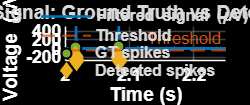

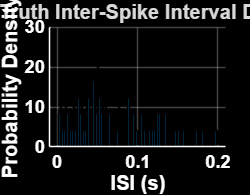

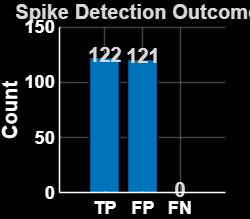

✅ Saved spike_time_trace.png (black background)
✅ Saved isi_hist.png (black background)
✅ Saved confusion_counts.png (black background)



% 13) Enhanced Plots (High Contrast)
% High-contrast colors
col_signal  = [0 0.45 0.74];   % Deep blue
col_thresh  = [0.85 0.33 0.1]; % Bright orange-red
col_gt      = [0.47 0.67 0.19];% Green
col_det     = [0.93 0.69 0.13];% Yellow-gold

set(0, 'DefaultAxesFontSize', 13, ...
       'DefaultAxesFontWeight', 'bold', ...
       'DefaultLineLineWidth', 1.5, ...
       'DefaultFigureColor', 'w');

% (a) Time trace excerpt with detections + GT
winStart_t = 2.0; winDur = 0.25;
i1 = round(winStart_t*Fs);
i2 = min(N, i1 + round(winDur*Fs));

figure('Name','Time Trace with Detections','Color','w','Position',[100 100 950 400]);
plot(t(i1:i2), 1e6*xf(i1:i2), 'Color', col_signal, 'LineWidth', 1.5); hold on;
yline(1e6*thr, '--', 'Threshold', 'Color', col_thresh, 'LineWidth', 1.4);
gt_in = spikeTimes(spikeTimes >= t(i1) & spikeTimes <= t(i2));
det_in = detTimes(detTimes >= t(i1) & detTimes <= t(i2));
scatter(gt_in, 1e6*interp1(t, xf, gt_in), 50, 'MarkerFaceColor', col_gt, ...
    'MarkerEdgeColor', 'k', 'LineWidth', 1.2, 'DisplayName', 'GT spikes');
scatter(det_in, 1e6*interp1(t, xf, det_in), 60, 'd', 'MarkerEdgeColor', col_det, ...
    'MarkerFaceColor', col_det, 'LineWidth', 1.2, 'DisplayName', 'Detected spikes');
legend({'Filtered signal (\muV)', 'Threshold', 'GT spikes', 'Detected spikes'}, ...
    'Location','best', 'Box','off');
xlabel('Time (s)'); ylabel('Voltage (\muV)');
title('Neural Signal: Ground Truth vs Detected Spikes');
grid on; box off;

% (b) ISI histogram
figure('Name','ISI Histogram (Ground Truth)','Color','w','Position',[120 120 450 350]);
edges = 0:0.002:0.2;
histogram(isi_gt, edges, 'Normalization','pdf','FaceColor',col_signal,'EdgeColor','k');
xlabel('ISI (s)'); ylabel('Probability Density');
title('Ground Truth Inter-Spike Interval Distribution');
grid on; box off;

% (c) Confusion counts bar chart
figure('Name','Detection Outcomes','Color','w','Position',[150 150 400 350]);
bar([TP FP FN], 'FaceColor', col_signal, 'EdgeColor', 'k');
set(gca,'XTickLabel',{'TP','FP','FN'});
ylabel('Count'); title('Spike Detection Outcomes');
text(1:length([TP FP FN]), [TP FP FN]+3, string([TP FP FN]), ...
    'HorizontalAlignment','center','FontWeight','bold','FontSize',12);
grid on; box off;

% 14) Save Plots (Black Background Version) 
% Exports clean PNGs with solid black background for dark theme visuals
figHandles = findall(0,'Type','figure');
saveNames  = {'spike_time_trace.png','isi_hist.png','confusion_counts.png'};

for k = 1:min(numel(figHandles), numel(saveNames))
    fig = figHandles(k);

    % Force black background and light text for contrast
    set(fig,'Color','k','Renderer','painters');    % black background
    ax = findall(fig,'Type','axes');
    set(ax,'Color','k','XColor','w','YColor','w'); % white axes and text
    drawnow;

    % Export (no transparency warning)
    exportgraphics(fig, saveNames{k}, 'BackgroundColor','black','Resolution',300);

    fprintf('✅ Saved %s (black background)\n', saveNames{k});
end


fprintf('\nAll figures exported successfully with black backgrounds.\n');


All figures exported successfully with black backgrounds.




% Helper 
function out = ternary(cond,a,b)
% Simple inline ternary operator replacement
if cond, out = a; else, out = b; end
end
